clear all
syms Kp Ki Kd

R = 100;
L = 10;
C = 0.01;

A = [0, 1;
    -1/(L*C),-R/L];
B = [0;
    1/L];
C = [1, 0];
D = 0;
[n_op, d_op] = ss2tf(A,B,C,D);
sys_op = tf(n_op,d_op)

sys_op =
 
        0.1
  ---------------
  s^2 + 10 s + 10
 
연속시간 전달 함수입니다.
모델 속성



Kp = 174.4847;
Ki = 294.1501;
Kd = 17.4948;
s = tf('s');
Contoller = Kp + Ki/s + Kd*s

Contoller =
 
  17.49 s^2 + 174.5 s + 294.2
  ---------------------------
               s
 
연속시간 전달 함수입니다.
모델 속성


sys_cl = feedback(Contoller*sys_op,1)

sys_cl =
 
     1.749 s^2 + 17.45 s + 29.42
  ---------------------------------
  s^3 + 11.75 s^2 + 27.45 s + 29.42
 
연속시간 전달 함수입니다.
모델 속성


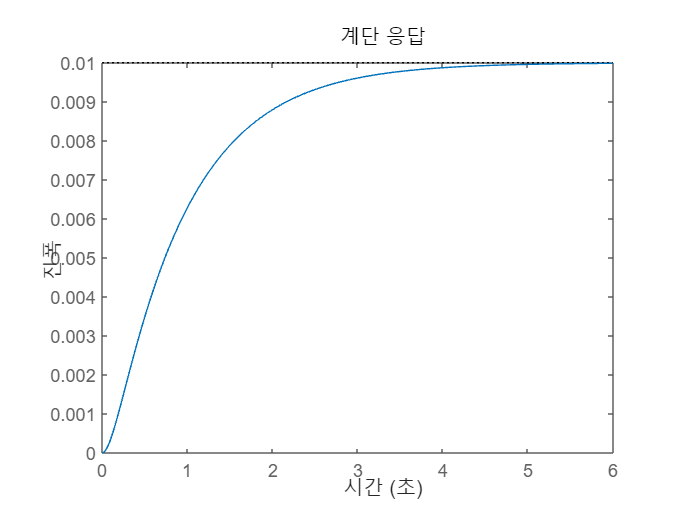


% 최종비교
% 제어 전
step(sys_op)

stepinfo(sys_op)

ans = 다음 필드를 포함한 struct :
         RiseTime: 1.9765
    TransientTime: 3.5917
     SettlingTime: 3.5917
      SettlingMin: 0.0090
      SettlingMax: 0.0100
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0100
         PeakTime: 6.1139


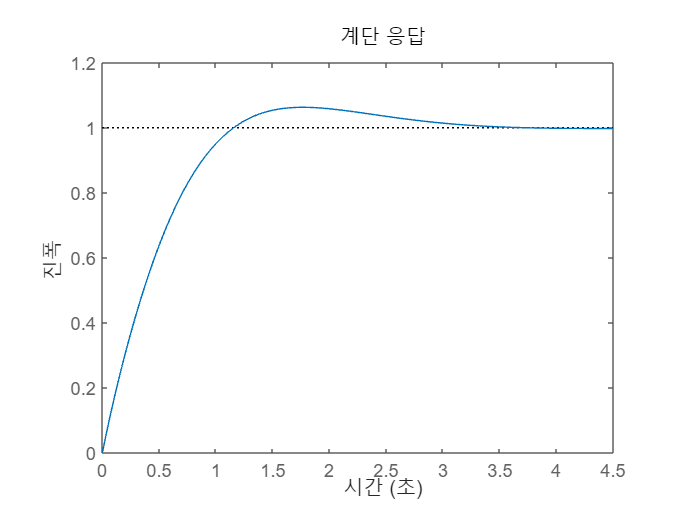

% 제어 후
step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.8205
    TransientTime: 2.8414
     SettlingTime: 2.8414
      SettlingMin: 0.9086
      SettlingMax: 1.0631
        Overshoot: 6.3103
       Undershoot: 0
             Peak: 1.0631
         PeakTime: 1.7625
